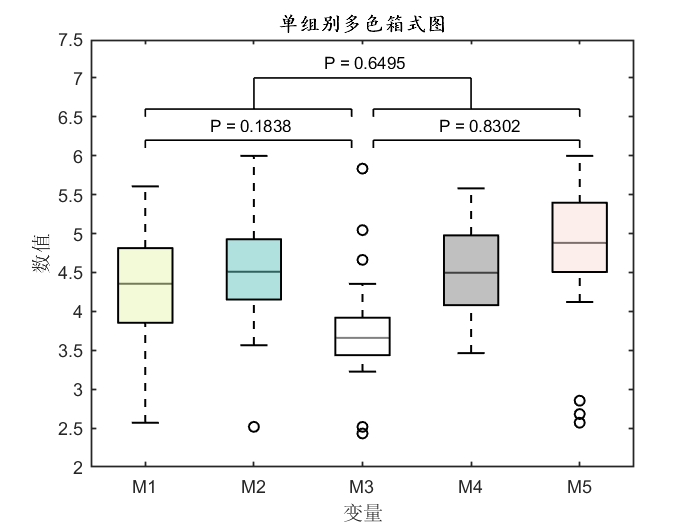

load data.mat;
% 坐标区域每组变量之间的标签
X ={' ','M1','M2','M3','M4','M5'};
%% 设置画图背景为白色
figure('color',[1 1 1]);
%% 设置配色
mycolor1 = [220 211 30;180 68 108;242 166 31;244 146 121;59 125 183]./255;
mycolor2 = [255 255 0;254 0 0;85 160 251;126 126 126;255 255 255]./255;
mycolor3 = [250 221 214;130 130 130;255 255 255;100 195 191;232 245 176]./255;
mycolor4 = [255 255 255;131 131 131;0 0 254;131 131 131;255 255 255]./255;
%参数依次为数据矩阵、颜色设置、标记符
box_figure = boxplot(data,'color',[0 0 0],'Symbol','o');
%设置线宽
set(box_figure,'Linewidth',1.2);
boxobj = findobj(gca,'Tag','Box'); %获取x,y对应的数据
for i = 1:5
    patch(get(boxobj(i),'XData'),get(boxobj(i),'YData'),mycolor3(i,:),'FaceAlpha',0.5,...
        'LineWidth',1.1); %通过x,y对应的数据确定铺色范围
end
hold on;
%% 设置坐标区域的参数
xlabel('变量','Fontsize',10,'FontWeight','bold','FontName','楷体');
ylabel('数值','Fontsize',10,'FontWeight','bold','FontName','楷体');
title('单组别多色箱式图','Fontsize',10,'FontWeight','bold','FontName','楷体');
set(gca,'Linewidth',1.1); %设置坐标区的线宽
set(gca,'Fontsize',11); % 设置坐标区字体大小
% 对X轴刻度与显示范围调整
set(gca,'Xlim',[0.5 5.5], 'Xtick', [0:1:5.5],'Xticklabel',X);
% 对Y轴刻度与显示范围调整
set(gca,'YTick', 2:0.5:7.5,'Ylim',[2 7.5]);
% 对刻度长度与刻度显示位置调整
set(gca, 'TickDir', 'in', 'TickLength', [.008 .008]);

%% 开始绘制显著性因素
hold on;
x1 = 1;
x2 = 2.9;
y1 = 6.1;
y2 = 6.2;
plot([x1,x1],[y1,y2],'k','Linewidth',1);
hold on;
plot([x2,x2],[y1,y2],'k','Linewidth',1);
hold on;
plot([x1,x2],[y2,y2],'k','Linewidth',1);
text((x1+x2)/2-0.35,y2+0.2,'P = 0.1838');
hold on;

x1 = 3.1;
x2 = 5;
y1 = 6.1;
y2 = 6.2;
plot([x1,x1],[y1,y2],'k','Linewidth',1);
hold on;
plot([x2,x2],[y1,y2],'k','Linewidth',1);
hold on;
plot([x1,x2],[y2,y2],'k','Linewidth',1);
text((x1+x2)/2-0.35,y2+0.2,'P = 0.8302');

hold on;
x1 = 1; 
x2 = 2.9;
y1 = 6.5;
y2 = 6.6;
plot([x1,x1],[y1,y2],'k','Linewidth',1);
hold on;
plot([x2,x2],[y1,y2],'k','Linewidth',1);
hold on;
plot([x1,x2],[y2,y2],'k','Linewidth',1);

hold on;
x1 = 3.1;
x2 = 5;
y1 = 6.5;
y2 = 6.6;
plot([x1,x1],[y1,y2],'k','Linewidth',1);
hold on;
plot([x2,x2],[y1,y2],'k','Linewidth',1);
hold on;
plot([x1,x2],[y2,y2],'k','Linewidth',1);

% 绘制最后一条大线

hold on;
x1 = 2;
x2 = 4;
y1 = 6.6;
y2 = 7;
plot([x1,x1],[y1,y2],'k','Linewidth',1);
hold on;
plot([x2,x2],[y1,y2],'k','Linewidth',1);
hold on;
plot([x1,x2],[y2,y2],'k','Linewidth',1);
text((x1+x2)/2-0.35,y2+0.2,'P = 0.6495');




mycolor = [0.862745098039216,0.827450980392157,0.117647058823529;...
    0.705882352941177,0.266666666666667,0.423529411764706;...
    0.949019607843137,0.650980392156863,0.121568627450980;...
    0.956862745098039,0.572549019607843,0.474509803921569;...
    0.231372549019608,0.490196078431373,0.717647058823529];